# **读入纳米棒数据并作图/保存图片**

% filedir = 'E:\work\SPR-DF\模拟\COMSOL\202230620_nanorod_去掉参数化解_这一版应该才是对的';
% files = dir(filedir);
% files(1:2) = [];
% files = namesort(files);
% M = zeros(201, 201, length(files));
% gamma = zeros(length(files), 1);
% for ii = 1:length(files)
%     load(fullfile(filedir, files(ii).name, 'aggregated_data.mat'));
%     gamma(ii) = mph_farfield.params.COMSOL.AR;
%     d_rod = mph_farfield.params.COMSOL.d_rod;
%     M(:, :, ii) = squeeze(sum(I,3));
%     f = figure;
%     imagesc(M(:, :, ii)); axis equal; axis off;
%     title(['d_{rod} = ', num2str(d_rod) 'nm, AR = ' num2str(gamma(ii))], 'fontsize', 15);
%     figpath = fullfile(filedir, files(ii).name, ...
%         ['d_rod = ', num2str(d_rod) 'nm, AR = ' num2str(gamma(ii))]);
%     saveMyfig(f, figpath);
% end

# **读入两个反应位点的数据并作图/保存图片**

% filedir = 'F:\work\SPR-DF\模拟\COMSOL\20230624_两个反应位点先后反应';
% files = dir(filedir);
% files(1:2) = [];
% files = namesort(files);
% M = zeros(201, 201, length(files)-1);
% gamma = zeros(length(files), 1);
% theta_span1 = gamma;
% theta_span2 = gamma;
% 
% for ii = 1:length(files)-1
%     load(fullfile(filedir, files(ii).name, 'aggregated_data.mat'));
%     gamma(ii) = mph_farfield.params.COMSOL.gamma;
%     theta_span1(ii) = mph_farfield.params.COMSOL.theta_span1;
%     theta_span2(ii) = mph_farfield.params.COMSOL.theta_span2;
%     M(:, :, ii) = squeeze(sum(I,3));
%     f = figure;
%     imagesc(M(:, :, ii)); axis equal; axis off;
%     title(['gamma = ', num2str(gamma(ii)) ...
%         ', theta_{span1} = ', num2str(theta_span1(ii)), ...
%         ', theta_{span2} = ', num2str(theta_span2(ii))], ...
%         'fontsize', 15);
%     figpath = fullfile(filedir, files(ii).name, ...
%         ['gamma = ', num2str(gamma(ii)) ...
%         ', theta_span1 = ', num2str(theta_span1(ii)), ...
%         ', theta_span2 = ', num2str(theta_span2(ii))]);
%     saveMyfig(f, figpath);
% end
% 

# **读入核壳结构数据并作图/保存图片**

% filedir = 'E:\work\SPR-DF\模拟\COMSOL\20230616_自由空间中核壳结构散射';
% files = dir(filedir);
% files(1:2) = [];
% files = namesort(files);
% M = zeros(201, 201, length(files));
% r_Ag = zeros(length(files), 1);
% for ii = 1:length(files)
%     load(fullfile(filedir, files(ii).name, 'aggregated_data.mat'));
%     r_particle = mph_farfield.params.COMSOL.r_particle;
%     r_Ag(ii) = mph_farfield.params.COMSOL.r_Ag;
%     M(:, :, ii) = squeeze(sum(I,3));
%     f = figure;
%     imagesc(M(:, :, ii)); axis equal; axis off;
%     title(['r_{particle} = ', num2str(r_particle) 'nm, r_{Ag} = ' num2str(r_Ag(ii)) 'nm'], 'fontsize', 15);
%     figpath = fullfile(filedir, files(ii).name, ...
%         ['r_particle = ', num2str(r_particle) 'nm, r_Ag = ' num2str(r_Ag(ii)) 'nm']);
%     saveMyfig(f, figpath);
% end

# **单块反应位点数据整理(hyper)**

**part 0: 罗列相关数据**

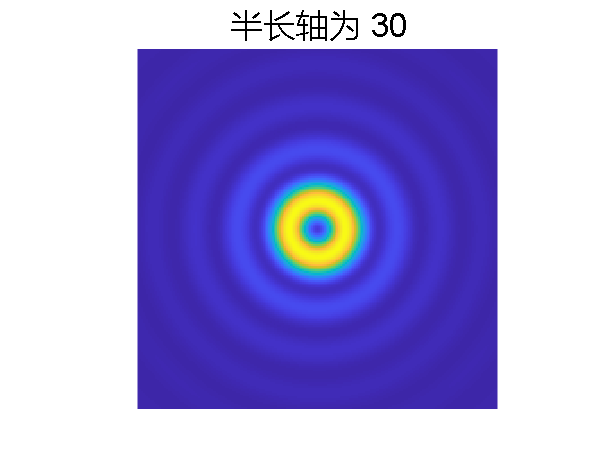

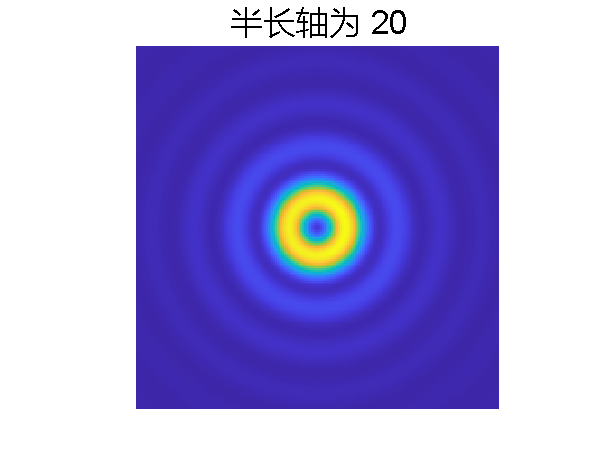

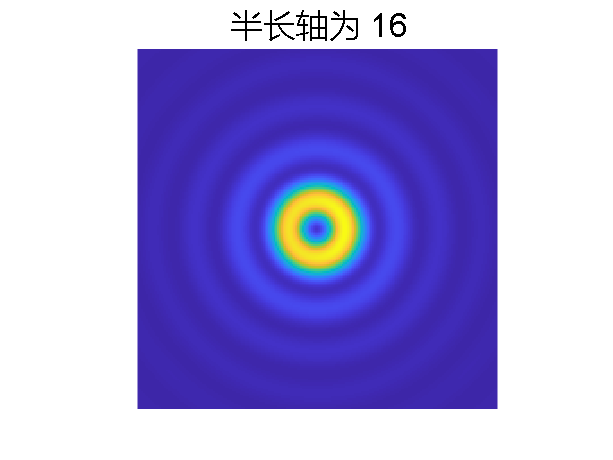

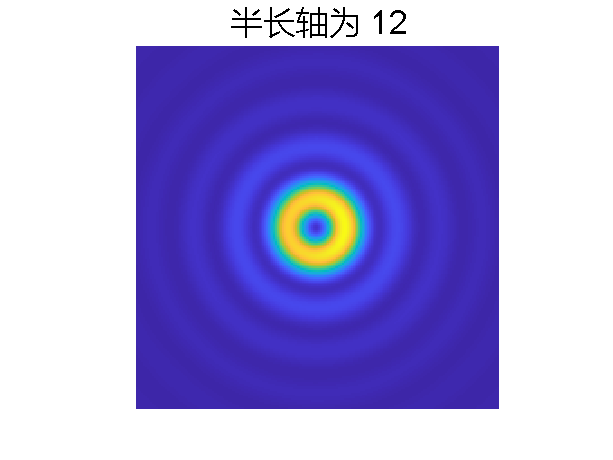

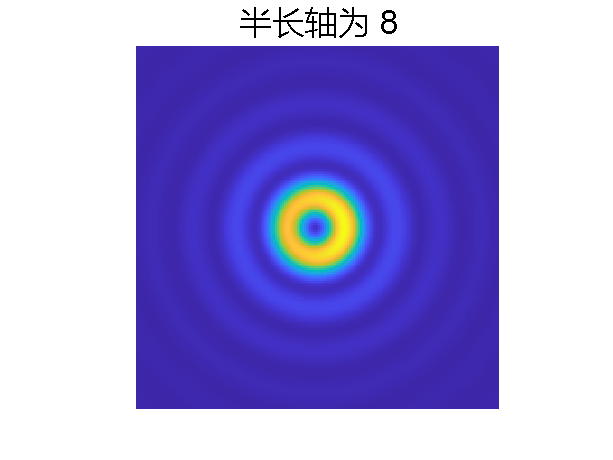

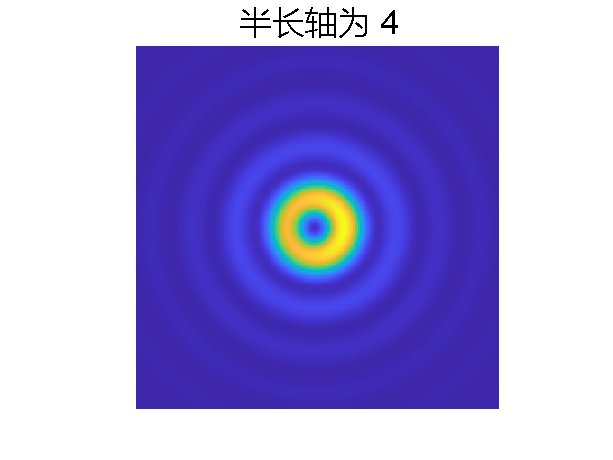

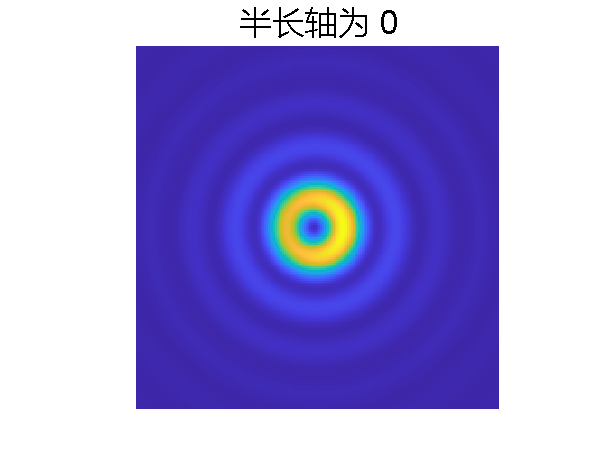

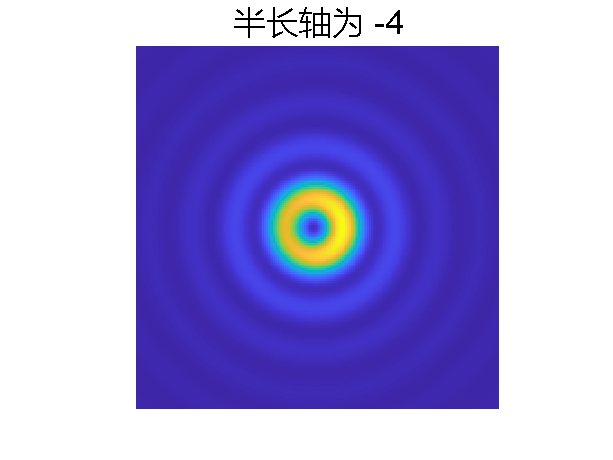

load('F:\work\SPR-DF\模拟\COMSOL\20230626_COMSOL_1patch_hyper\Result.mat');
savedir = 'F:\work\SPR-DF\模拟\COMSOL\20230626_COMSOL_1patch_hyper';
v = [30 20:-4:-20 -30];
I = squeeze(sum(I, 3));
for ii = 1:length(v)
    f = figure;
    imagesc(I(:, :, ii));
    axis equal; axis off;
    figname = ['半长轴为 ' num2str(v(ii))];
    title(figname, FontSize=20);
    % figpath = fullfile(savedir, ['result_' num2str(ii)], figname);
    % saveMyfig(f, figpath);
end

**part 1: 反应体积**

**本小节所求，a是双曲线的半实轴长度，如comsol文件所注释。V是AgCl的体积比。**

x = -50:0.4:50;
y = x;
z = x + 0.5;
[X, Y, Z1] = meshgrid(x, y, z);
X = reshape(X, [], 1);
Y = reshape(Y, [], 1);
Z1 = reshape(Z1, [], 1);
R = hypot(hypot(X, Y), Z1);
c_Ag = 30;
a = (30:-1:-30);
V = zeros(length(a), 1);
for ii = 1:length(a)
    z = a(ii)*sqrt(1+hypot(X, Y).^2/(c_Ag^2-a(ii)^2));
    ind = zeros(size(z));
    k = 0;
    for jj = 1:length(R)
        if R(jj) < c_Ag && Z1(jj) > z(jj)
            k = k+1;
            ind(k) = jj;
        end
    end
    ind(ind ==0) = [];
    V(ii) = length(ind);
end
V = V/sum(R<c_Ag,'all');

**part 2: 读入模拟数据**

**本小节得到的数据，v是comsol模型中设置的双曲线的半实轴参数，而I则是各参数对应的强度值。**

load('F:\work\SPR-DF\模拟\COMSOL\20230626_COMSOL_1patch_hyper\Result.mat');
v = [30 20:-4:-20 -30];
I = squeeze(sum(I, [1 2 3]));
figure; hold on
k = 0:0.01:1;
x = spline(a, V, v); y = I;
plot(k, spline(x, y, k), 'LineWidth', 3);
xlabel('AgCl 所占体积分数', fontsize = 20)
ylabel('Intensity (a.u.)', fontsize = 20)

plot(spline(a, V, v), I, '*', 'markersize', 8, 'linewidth', 2);
xlabel('AgCl 所占体积分数', fontsize = 20)
ylabel('Intensity (a.u.)', fontsize = 20)
title('模拟得到的强度随反应程度变化趋势', fontsize = 20)
axis square
legend('插值结果', '计算结果', 'fontsize', 15, 'box', 'off')

**part 3: 动力学模拟**

**本小节根据一个简单的一阶动力学公式，计算在此动力学公式下，颗粒的光强随时间的变化曲线，其中k0是反应动力学参数，t是反应时间。c_Ag是反应过程中的归一化Ag原子数。**

% k0 = 1; t = -10:0.1:20; c_Ag = (t<0) + (t>=0).*exp(-k0*t);
% figure
% yyaxis left
% plot(t, c_Ag, 'linewidth', 3);
% xlabel('Time (s)', fontsize = 20)
% ylabel('f (%)', fontsize = 20)
% title('已反应的银原子数比例', fontsize = 20)
% ylim([-0.1 1.1]);
% 
% yyaxis right
% plot(t, spline(x, y, 1 - c_Ag)/spline(x, y, 0), 'linewidth', 3);
% xlabel('Time (s)', fontsize = 20)
% ylabel('Intensity (a.u.)', fontsize = 20)
% title('模拟得到的强度随反应程度变化趋势', fontsize = 20)
% ylim([-0.1 4.1]);
% axis square
% legend('反应进程', '归一化强度', 'fontsize', 15, 'box', 'off')

# **显示辐射图**

**本脚本是一个临时脚本，用于从计算出的远场数据中展示三维空间的辐射图**

% theta = mph_farfield.result.phi_illum_20.theta_out;
% phi = mph_farfield.result.phi_illum_20.phi_out;
% s = power(vecnorm(mph_farfield.result.phi_illum_20.E_farfield,2,2),2);
% [x, y, z] = sph2cart(phi, pi/2-theta, s);
% figure
% scatter3(x, y, z); axis equal

# **根据远场数据计算散射图案**

% savepath = 'D:\WJH\Ag_AgCl\Simulation\COMSOL\202230619_nanorod';
% fields = dir(savepath);
% fields(1:3) = [];
% theta_illum = 64;
% gamma = 2:0.5:4;
% I= zeros(201, 201, 18, length(gamma));
% for ii = 1:length(gamma)
%     ii
%     load(fullfile(savepath, ['result_' num2str(ii)], 'aggregated_data.mat'));
%     p_36 = mphimage(mph_farfield);
%     I(:, :, :, ii) = p_36.I;
%     figure
%     imagesc(sum(p_36.I, 3)); axis equal; axis off
%     title(['AR=' num2str(gamma(ii))]);
% end
% save(fullfile(savepath,'Result.mat'), 'I', 'p', '-v7.3');